**Project 1: Vehicle Braking Distance Simulator (Mechanical / Automotive)**

Objective: Model the stopping distance of a vehicle under different initial speeds and braking forces.

Core Tasks:

`•` Simulate vehicle deceleration using time-stepped logic

`•` Compare stopping distances for multiple initial velocities

Key Deliverables: Stopping distance plots and written interpretation of safety implications

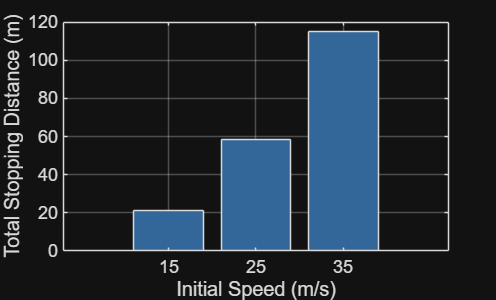

%% 1. Define Constants
v0 = [15, 25, 35];  % Creates a list (vector) of three initial speeds in meters per second
mass = 1500;        % Defines the car's mass in kg
force = 8000;       % Defines how hard the brakes are pushing in Newtons.

% Calculate constant deceleration (magnitude)
a = force / mass; %Newtons law of motion is defined as F=ma, we need acceleration so this is rearranged for a=F/m

%% 2. Calculate Stopping Distances
stopping_distances = (v0.^2) ./ (2 * a); % This line uses the physics formula: d = (v^2) / (2a). This is a kinematics equation

%% 3. Create a Visualization
figure; % Opens a new window for the graph.
bar(v0, stopping_distances, 'FaceColor', [0.2 0.4 0.6]); % Creates a bar chart using the speeds for the x-axis and distances for the y-axis.
grid on; % Creates grid lines on the graph
xlabel('Initial Speed (m/s)'); % Labels the x-axis the initial speed 
ylabel('Total Stopping Distance (m)'); % Labels the y-axis of the graph

title('Vehicle Braking Distance vs. Initial Speed'); % Titles the graph 

Error using matlab.graphics.internal.validatePartialPropertyNames
Unrecognized property height for class Text.

Error in labelcheck (line 29)
propNames = validatePartialPropertyNames(...
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in title (


% Add text labels on top of bars
for i = 1:length(v0) % This loop goes through each bar and prints the exact distance number 
    text(v0(i), stopping_distances(i) + 5, [num2str(round(stopping_distances(i),1)), ' m'], ...
        'Horiz','center'); % slightly above it (+ 5) so you don't have to guess based on the axis.
end